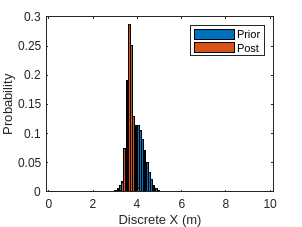

%%% Complete the parts denoted by "???"


E = @(x, p) sum(x.*p); % This is the function to calculate the Expected value.

%%% Part one
%%Robot lives in 1D space�
x_min = 0; x_max = 10; %meter�
x=linspace(x_min,x_max,100); % converted to 100 bins�
pd_x = makedist('Normal','mu',4,'sigma',0.35); % robot position belief�
p_x = pdf(pd_x,x); % P(x) �
eta = sum(p_x);
p_x = 1/eta*p_x; % now p sums up to 1�
bar(x,p_x)
xlabel("Discrete X (m)")
ylabel("Probability")
legend("Prior")

sensor_noise = makedist('Normal','mu',0,'sigma',0.15); % sensor noise model�
z_sensor = 3.6; % measurement value�
pz_x = pdf(sensor_noise, z_sensor - x); % p(z|x) for all x�
px_z = pz_x.*p_x;
eta = sum(px_z);
px_z = 1/eta*px_z; % now p sums up to 1
hold on
bar(x,px_z)
legend("Prior", "Post")
hold off

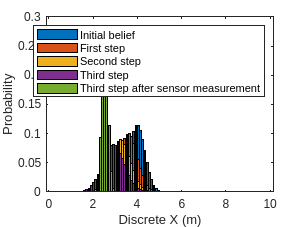

%%% Parts 2 and 3
bar(x,p_x)
xlabel("Discrete X (m)")
ylabel("Probability")
legend("Prior")
hold on
w_noise = makedist('Normal','mu',0,'sigma',0.2);
for i = 1:3
    % sensor noise model
    u = -0.1*E(x, p_x); % control action
    for k = 1:100
        p_motion = pdf(w_noise, x(k)-x-u); %p(x'|x,u)
        p_xpr(k) = sum(p_motion.*p_x);
    end
    eta = sum(p_xpr);
    p_xpr = 1/eta*p_xpr; % now p sums up to 1
    bar(x,p_xpr);
    hold on
    p_x = p_xpr;
end


z_sensor = 2.5; % measurement value�
pz_x = pdf(sensor_noise, z_sensor - x); % p(z|x) for all x�
px_z = pz_x.*p_x;
eta = sum(px_z);
px_z = 1/eta*px_z; % now p sums up to 1
hold on
bar(x,px_z)
legend("Initial belief", "First step", "Second step", "Third step", "Third step after sensor measurement")